# `线性代数相关的函数`

本节我们将介绍MATLAB在线性代数中的一些常用函数，以下内容大多仅涉及到初等线性代数的知识，同学们可以看本章第一节复习。

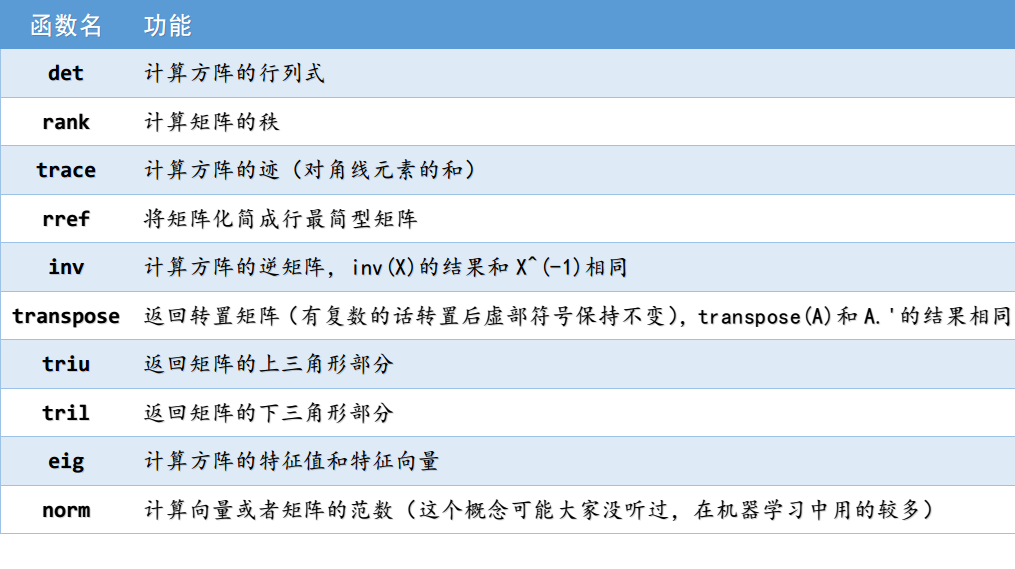

`最前面的几个函数都很简单，我们举几个例子：`

**det  计算方阵的行列式**

A = [6 2 1;
    10 10 8;
    4 3 3];
det(A)

ans = 30.0000

**rank 计算矩阵的秩**

A = [9 8 8 5;
    7 4 2 6;
    7 4 2 6];
rank(A)

ans = 2

**trace  计算方阵的迹（对角线元素的和）**

A = [4 6 5;
    1 3 3;
    6 7 6];
trace(A)

ans = 13

**rref  将矩阵化简成行最简型矩阵**

A = [2 4 4 1;
    6 10 8 7;
    1 8 9 1];
rref(A)

ans =     1.0000         0         0   -0.5000
         0    1.0000         0    3.0000
         0         0    1.0000   -2.5000


**inv   计算方阵的逆矩阵，inv(X)的结果和X^(-1)相同**

A =  [2 3 4;
    3 2 5;
    3 7 8];
inv(A)

ans =     3.8000   -0.8000   -1.4000
    1.8000   -0.8000   -0.4000
   -3.0000    1.0000    1.0000


**transpose 返回转置矩阵（有复数的话转置后虚部符号保持不变），transpose(A)和A.'的结果相同**

A = [1 2;
    3 8;
    1 4];
transpose(A)

ans =      1     3     1
     2     8     4


### **triu**`函数和`**tril**`函数功能类似，可分别用来返回矩阵的上三角形部分和下三角形部分。`

`triu(A,k)``返回``A``的第``k``条对角线上以及该对角线上方的元素，其他位置元素用``0``填充。`

`tril(A,k)``返回``A``的第``k``条对角线上以及该对角线下方的元素，其他位置元素用``0``填充。`

`默认值``k = 0``是主对角线，``k > 0``位于主对角线上方，而``k < 0``位于主对角线下方。`

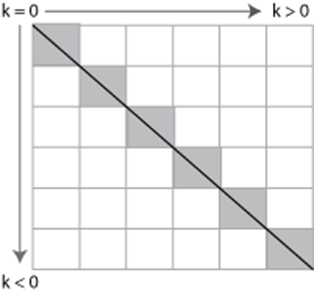

A = [9     6     8     6     2
    9     1     2     4     0
    7     2     5     1     4
    6     8     6     5     2
    9     5     1     2     1];
triu(A)

ans =      9     6     8     6     2
     0     1     2     4     0
     0     0     5     1     4
     0     0     0     5     2
     0     0     0     0     1


triu(A,1)

ans =      0     6     8     6     2
     0     0     2     4     0
     0     0     0     1     4
     0     0     0     0     2
     0     0     0     0     0


triu(A,-1)

ans =      9     6     8     6     2
     9     1     2     4     0
     0     2     5     1     4
     0     0     6     5     2
     0     0     0     2     1


tril(A)

ans =      9     0     0     0     0
     9     1     0     0     0
     7     2     5     0     0
     6     8     6     5     0
     9     5     1     2     1


tril(A,1)

ans =      9     6     0     0     0
     9     1     2     0     0
     7     2     5     1     0
     6     8     6     5     2
     9     5     1     2     1


tril(A,-1)

ans =      0     0     0     0     0
     9     0     0     0     0
     7     2     0     0     0
     6     8     6     0     0
     9     5     1     2     0


`练习题：生成一个n阶的对称矩阵，里面的每个元素都是位于区间[0, 9]中的随机整数。`

`n=3时，一个符合条件的三阶对称矩阵可能如下所示：`


$$\left\lbrack \begin{array}{ccc}
5 & 2 & 7\\
2 & 3 & 4\\
7 & 4 & 1
\end{array}\right\rbrack$$


我们可以将它分解成三个部分：

$\left\lbrack \begin{array}{ccc}
5 & 2 & 7\\
2 & 3 & 4\\
7 & 4 & 1
\end{array}\right\rbrack$=$\left\lbrack \begin{array}{ccc}
0 & 2 & 7\\
0 & 0 & 4\\
0 & 0 & 0
\end{array}\right\rbrack$+$\left\lbrack \begin{array}{ccc}
0 & 0 & 0\\
2 & 0 & 0\\
7 & 4 & 0
\end{array}\right\rbrack$+$\left\lbrack \begin{array}{ccc}
5 & 0 & 0\\
0 & 3 & 0\\
0 & 0 & 1
\end{array}\right\rbrack$

显然，第一个部分和第二个部分是转置关系，我们只需要生成两个中的一个即可。

假设我们要生成第一个随机矩阵，它是一个上三角形矩阵，这里的2 7 4三个元素可以被替换成区间[0, 9]中的随机整数。

考虑一般的情况：对于一个n阶的方阵，需要生成的上三角形矩阵中有$\frac{n\left(n-1\right)}{2}$个随机数

而第三个部分是一个对角矩阵，可以使用diag函数生成，里面有n个随机数。

n = 5;  
num = n*(n-1)/2;  % 上三角形矩阵要生成多少个随机数 
A = zeros(n)  % 初始化A矩阵中全为0

A =      0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0


x = randi([0,9],num,1)

x =      8
     9
     1
     9
     6
     0
     2
     5
     9
     9


true(n)

ans = 5×5 logical 数组
   1   1   1   1   1
   1   1   1   1   1
   1   1   1   1   1
   1   1   1   1   1
   1   1   1   1   1


triu(true(n),1)

ans = 5×5 logical 数组
   0   1   1   1   1
   0   0   1   1   1
   0   0   0   1   1
   0   0   0   0   1
   0   0   0   0   0


A(triu(true(n),1)) = x

A =      0     8     9     9     2
     0     0     1     6     5
     0     0     0     0     9
     0     0     0     0     9
     0     0     0     0     0


A'

ans =      0     0     0     0     0
     8     0     0     0     0
     9     1     0     0     0
     9     6     0     0     0
     2     5     9     9     0


A = A+A'

A =      0     8     9     9     2
     8     0     1     6     5
     9     1     0     0     9
     9     6     0     0     9
     2     5     9     9     0


% diag(1:3)
y = randi([0,9],n,1)

y =      1
     9
     9
     4
     8


diag(y)

ans =      1     0     0     0     0
     0     9     0     0     0
     0     0     9     0     0
     0     0     0     4     0
     0     0     0     0     8


A = A+diag(y)

A =      1     8     9     9     2
     8     9     1     6     5
     9     1     9     0     9
     9     6     0     4     9
     2     5     9     9     8


A'

ans =      1     8     9     9     2
     8     9     1     6     5
     9     1     9     0     9
     9     6     0     4     9
     2     5     9     9     8


A' == A

ans = 5×5 logical 数组
   1   1   1   1   1
   1   1   1   1   1
   1   1   1   1   1
   1   1   1   1   1
   1   1   1   1   1


`以后我们学了循环语句后，还可以利用循环语句生成，虽然循环语句更直观且代码易于编写，但直接基于矩阵操作在`MATLAB`中通常更高效，尤其是对于大型矩阵。`

`此外，也有同学想到了这种思路：`

n = 1000;
A = randi([0,9],n)

A =      1     5     3     8     6     3     6     5     6     2     2     3     2     6     6     7     0     8     5     7     1     8     4     0     5     3     6     3     3     0     0     1     1     6     0     4     1     7     1     6     6     4     7     8     5     9     6     5     2     1
     4     1     0     4     1     6     3     0     5     6     4     3     4     9     5     6     8     5     0     4     0     1     5     1     4     0     5     7     6     1     6     5     7     2     3     4     1     4     3     3     6     5     5     1     5     0     1     1     4     0
     9     9     2     5     2     8     7     9     4     9     1     1     9     9     8     4     7     0     6     7     4     3     0     3     7     5     7     4     8     0     6     6     9     3     3     3     2     8     9     8     2     3     9     2     0     2     6     5     9     2
     7     2     3     4     7     7     0     6     8     4     3     3     3     7     0   

B = triu(A)

B =      1     5     3     8     6     3     6     5     6     2     2     3     2     6     6     7     0     8     5     7     1     8     4     0     5     3     6     3     3     0     0     1     1     6     0     4     1     7     1     6     6     4     7     8     5     9     6     5     2     1
     0     1     0     4     1     6     3     0     5     6     4     3     4     9     5     6     8     5     0     4     0     1     5     1     4     0     5     7     6     1     6     5     7     2     3     4     1     4     3     3     6     5     5     1     5     0     1     1     4     0
     0     0     2     5     2     8     7     9     4     9     1     1     9     9     8     4     7     0     6     7     4     3     0     3     7     5     7     4     8     0     6     6     9     3     3     3     2     8     9     8     2     3     9     2     0     2     6     5     9     2
     0     0     0     4     7     7     0     6     8     4     3     3     3     7     0   

C = triu(A,1)

C =      0     5     3     8     6     3     6     5     6     2     2     3     2     6     6     7     0     8     5     7     1     8     4     0     5     3     6     3     3     0     0     1     1     6     0     4     1     7     1     6     6     4     7     8     5     9     6     5     2     1
     0     0     0     4     1     6     3     0     5     6     4     3     4     9     5     6     8     5     0     4     0     1     5     1     4     0     5     7     6     1     6     5     7     2     3     4     1     4     3     3     6     5     5     1     5     0     1     1     4     0
     0     0     0     5     2     8     7     9     4     9     1     1     9     9     8     4     7     0     6     7     4     3     0     3     7     5     7     4     8     0     6     6     9     3     3     3     2     8     9     8     2     3     9     2     0     2     6     5     9     2
     0     0     0     0     7     7     0     6     8     4     3     3     3     7     0   

CC = C'

CC =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     5     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     3     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     8     4     5     0     0     0     0     0     0     0     0     0     0     0     0  

A = B + CC

A =      1     5     3     8     6     3     6     5     6     2     2     3     2     6     6     7     0     8     5     7     1     8     4     0     5     3     6     3     3     0     0     1     1     6     0     4     1     7     1     6     6     4     7     8     5     9     6     5     2     1
     5     1     0     4     1     6     3     0     5     6     4     3     4     9     5     6     8     5     0     4     0     1     5     1     4     0     5     7     6     1     6     5     7     2     3     4     1     4     3     3     6     5     5     1     5     0     1     1     4     0
     3     0     2     5     2     8     7     9     4     9     1     1     9     9     8     4     7     0     6     7     4     3     0     3     7     5     7     4     8     0     6     6     9     3     3     3     2     8     9     8     2     3     9     2     0     2     6     5     9     2
     8     4     5     4     7     7     0     6     8     4     3     3     3     7     0   

这种思路会导致浪费近一半的随机数，当n很大时会降低代码的运行效率。

### `eig函数可用来计算方阵的特征值和特征向量``，它有两种最基础的用法：`

- `e = eig(A) ``返回一个列向量，``e``中包含方阵``A``的所有特征值。`

- `[V,D] = eig(A) ``返回特征向量构成的矩阵``V``和特征值构成的对角矩阵``D``，``V``中的每一列就是``D``中对应特征值的特征向量。`

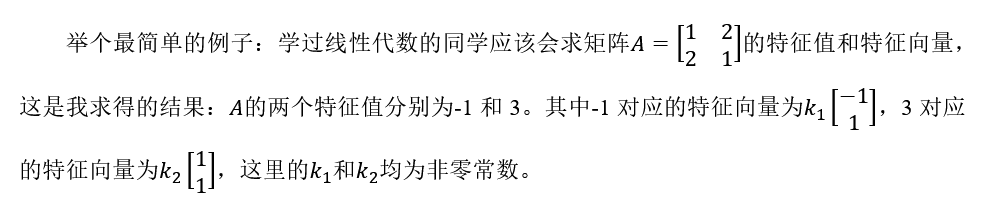

`我们用`MATLAB`来验算下：`

A = [3 -1;
     -1 3];
e = eig(A)

e =      2
     4


[V,D] = eig(A)

V =    -0.7071   -0.7071
   -0.7071    0.7071


D =      2     0
     0     4


有同学会有疑惑，为什么MATLAB算出来的特征向量这么奇怪？

这是因为特征值对应的特征向量不是唯一的，前面可以乘以任意的非零常数。在MATLAB中，求出的特征向量的模长为1。

再来看一道线性代数的题目：

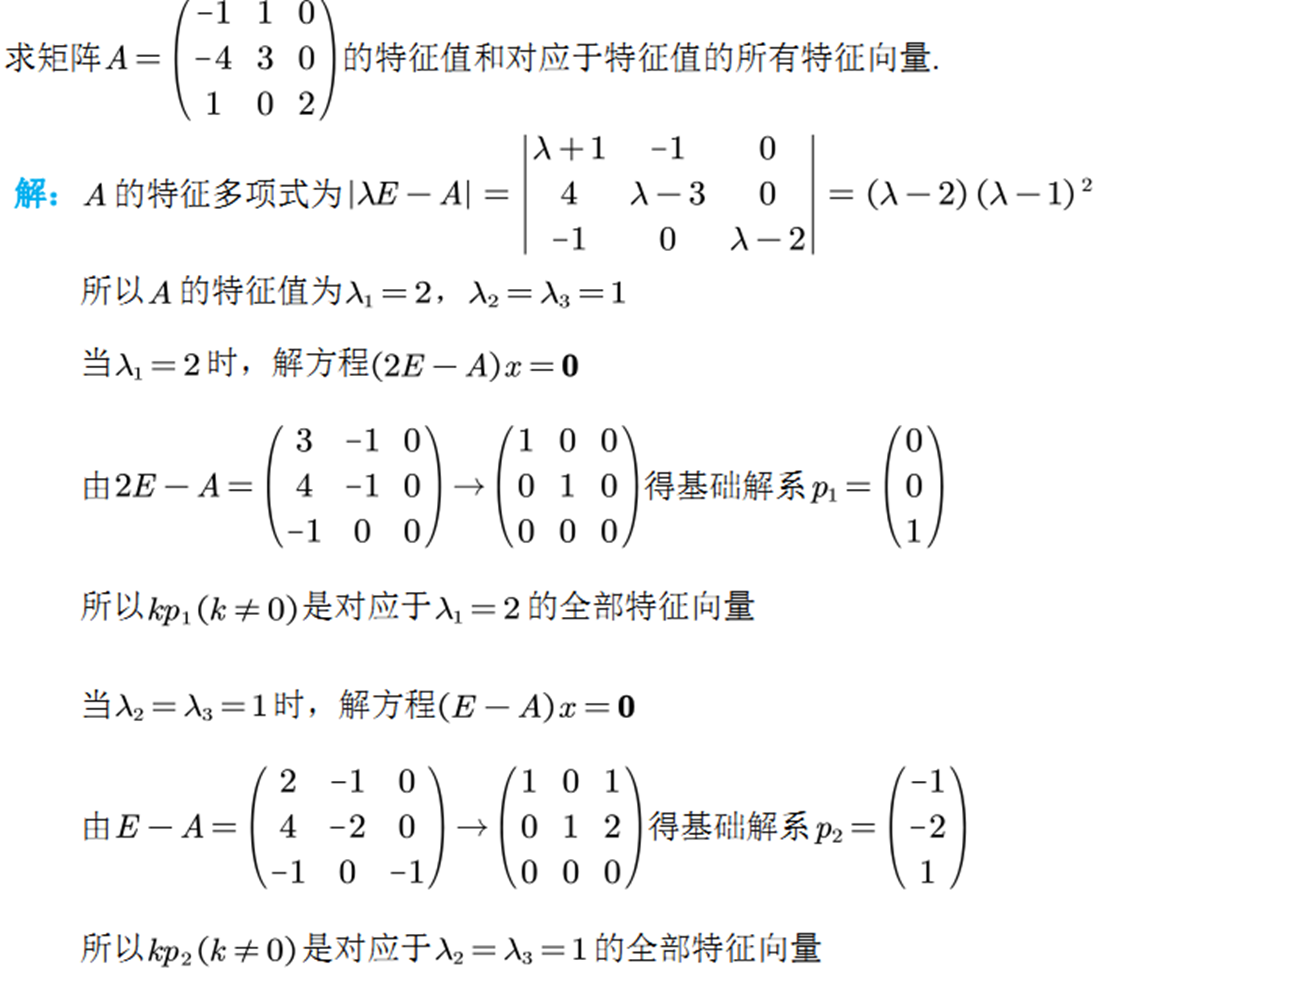

A = [-1 1 0;
     -4 3 0;
     1 0 2];
e = eig(A)

e =      2
     1
     1


[V,D] = eig(A)

V =          0    0.4082    0.4082
         0    0.8165    0.8165
    1.0000   -0.4082   -0.4082


D =      2     0     0
     0     1     0
     0     0     1


A = [17 24 1 8 15;
    23 5 7 14 16;
    4 6 13 20 22;
    10 12 19 21 3;
    11 18 25 2 9];
[V,D] = eig(A)

V =    -0.4472    0.0976   -0.6330    0.6780   -0.2619
   -0.4472    0.3525    0.5895    0.3223   -0.1732
   -0.4472    0.5501   -0.3915   -0.5501    0.3915
   -0.4472   -0.3223    0.1732   -0.3525   -0.5895
   -0.4472   -0.6780    0.2619   -0.0976    0.6330


D =    65.0000         0         0         0         0
         0  -21.2768         0         0         0
         0         0  -13.1263         0         0
         0         0         0   21.2768         0
         0         0         0         0   13.1263


`练习题：`请你将上方A矩阵的特征值从大到小降序排列，对应的特征向量的顺序也要跟着特征值的顺序改变。

e = diag(D)  % 取出特征值

e =    65.0000
  -21.2768
  -13.1263
   21.2768
   13.1263


[sort_e, ind] = sort(e, 'descend')  % 将特征值降序排列

sort_e =    65.0000
   21.2768
   13.1263
  -13.1263
  -21.2768


ind =      1
     4
     5
     3
     2


D_new = diag(sort_e)

D_new =    65.0000         0         0         0         0
         0   21.2768         0         0         0
         0         0   13.1263         0         0
         0         0         0  -13.1263         0
         0         0         0         0  -21.2768


V_new = V(:, ind)

V_new =    -0.4472    0.6780   -0.2619   -0.6330    0.0976
   -0.4472    0.3223   -0.1732    0.5895    0.3525
   -0.4472   -0.5501    0.3915   -0.3915    0.5501
   -0.4472   -0.3525   -0.5895    0.1732   -0.3223
   -0.4472   -0.0976    0.6330    0.2619   -0.6780


### **norm**`函数: 用来计算向量或者矩阵的范数`

`范数这个概念大家可能没听过，它在机器学习中用的较多。`

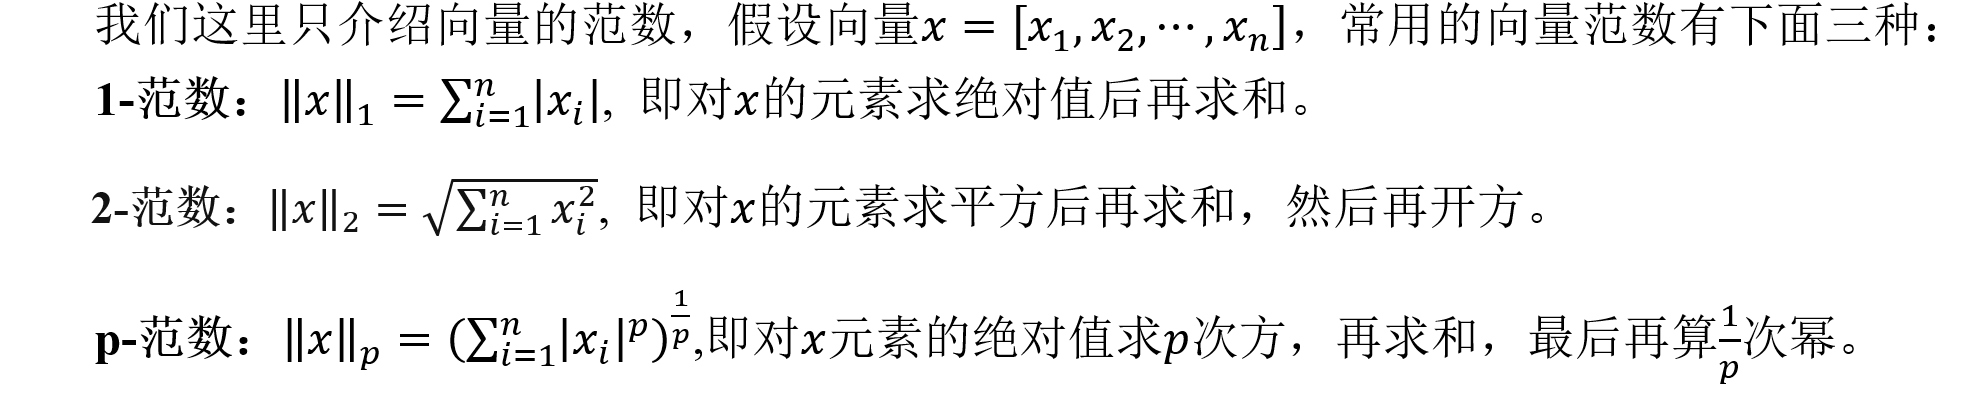

`在``MATLAB``中的调用方法分别为：``norm(x,1)``、``norm(x,2)``和``norm(x,p), p``是一个正实数。`

`事实上，``1-``范数和``2-``范数都属于``p-``范数的特例，``MATLAB``中``p``默认取``2``，即``norm(x)``表示计算``2-``范数``。`

x = [2 -4 -4 0];
a1 = norm(x,1)  

a1 = 10

a2 = norm(x,2)  % 等价于norm(x)

a2 = 6

a3 = norm(x,3)

a3 = 5.1426

事实上，如果你不会norm函数，也可以用我们之前的方法计算向量的范数：

- p-`范数等价于：`sum(abs(x).^p) ^ (1/p)  % `这里的`1/p`要加括号`

`拓展：范数和距离的联系`

`（`**1**`）欧式距离`

`欧式距离是最常见的两点之间距离定义的方法，又被称为欧几里得度量，它定义于欧几里得空间中。`

`点`$x=\left( x_1,x_2,\cdots ,x_n \right) $`和点`$y=\left( y_1,y_2,\cdots ,y_n \right) $ `之间的欧氏距离为：`


$$d_{x,y}^{\text{欧氏距离}}=\sqrt{\left( x_1-y_1 \right) ^2+\left( x_2-y_2 \right) ^2+\cdots +\left( x_n-y_n \right) ^2}=\sqrt{\sum_{i=1}^n{\left( x_i-y_i \right) ^2}}$$


`显然，把`$x$`和`$y$`视为两个向量，则`$d_{x,y}^{\textrm{欧氏距离}} ={\left\|x-y\right\|}_2$  `（将`x`和`y`向量作差后计算`2-`范数）`

例如：三维空间中x和y两点的坐标分别为：

x = [5 3 1];
y = [3 1 0];

则x和y的欧氏距离为：

norm(x-y)  % sum((x-y).^2) ^ (1/2)

ans = 3

`（`**2**`）曼哈顿距离`

`假设城市所有的道路是平行且垂直的，如下图所示，你需要驾车从`X`点到达`Y`点，那么你的驾驶距离应该如何计算？`

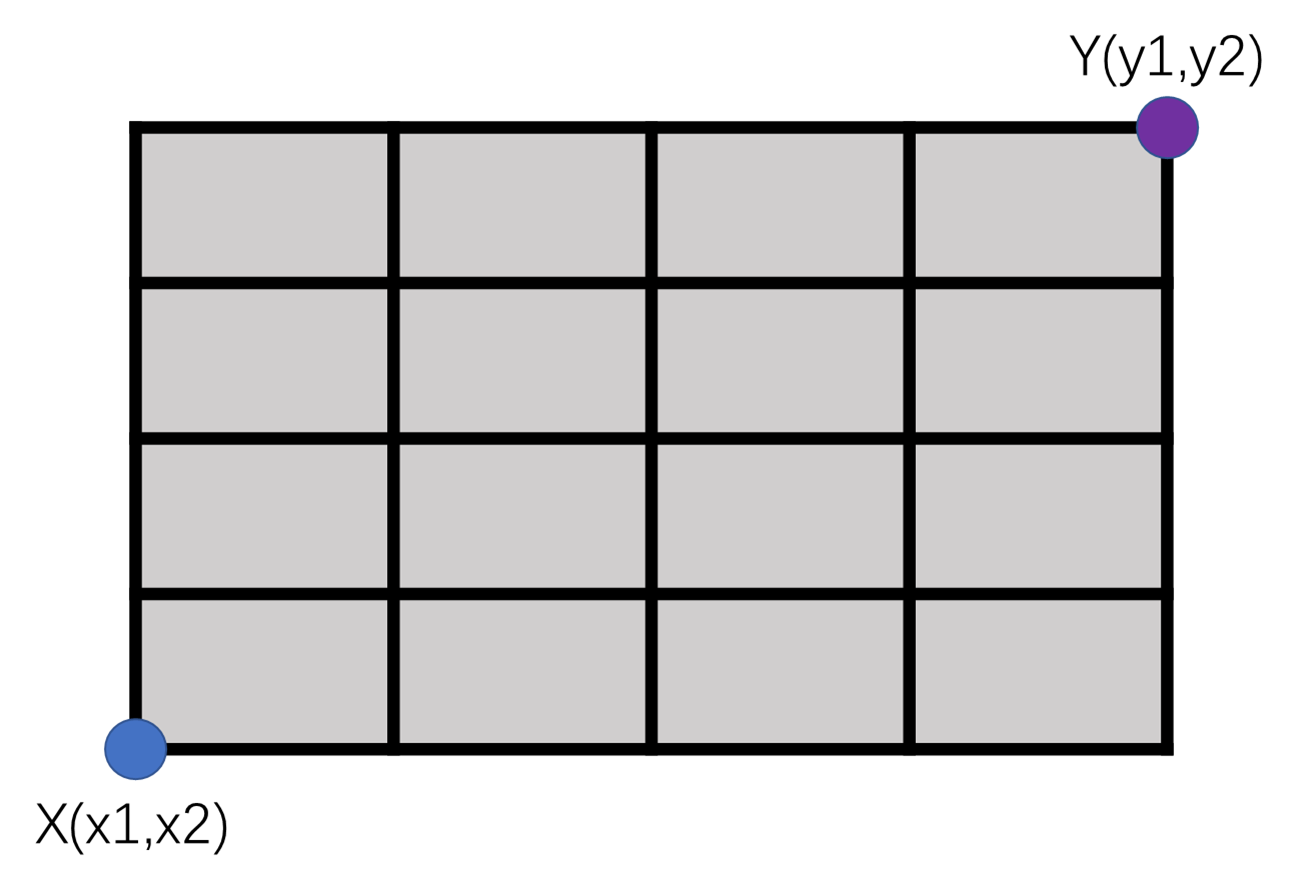

`你能直接计算`X`和`Y`两点之间的欧式距离作为你的驾驶距离吗？当然不行，除非你开的飞机。`

`这时候，我们可以使用曼哈顿距离来表示实际的驾驶距离。`

x和y`之间的曼哈顿距离为：`


$$d_{x,y}^{\text{曼哈顿距离}}=\left| x_1-y_1 \right|+\left| x_2-y_2 \right|+\cdots +\left| x_n-y_n \right|=\sum_{i=1}^n{\left| x_i-y_i \right|}$$


`把`$x$`和`$y$`视为两个向量，则`$d_{x,y}^{\textrm{曼哈顿}\textrm{距离}} ={\left\|x-y\right\|}_1$  `（将`x`和`y`向量作差后计算1`-`范数）`

例如：二维平面中x和y两点的坐标分别为：

x = [1 5];
y = [4 9];

则x和y的欧氏距离为：

norm(x-y,1)  % sum(abs(x-y))

ans = 7

`（`**3**`）闵氏距离`**(Minkowski Distance)**

`闵氏距离（闵可夫斯基距离）不是一种特定的距离，而是一组距离的定义。`

x和y `之间的闵氏距离为：`


$$d_{x,y}^{\text{闵式距离}}=\left( \left| x_1-y_1 \right|^p+\left| x_2-y_2 \right|^p+\cdots +\left| x_n-y_n \right|^p \right) ^{\frac{1}{p}}=\left( \sum_{i=1}^n{\left| x_i-y_i \right|^p} \right) ^{\frac{1}{p}}
$$


`其中`p`是一个正数，当`p=1`时就是曼哈顿距离，当`p=2`时，就是欧氏距离。`

`把` x和y `视为两个向量，则`$d_{x,y}^{\textrm{闵式}\textrm{距离}} ={\left\|x-y\right\|}_p$ .`（将`x`和`y`向量作差后计算`p-`范数）`

`本节我们介绍的函数大多只涉及到初等线性代数的知识，学过高等代数或者数值分析课程的同学可以点击点击下方链接学习`Matlab`中更多线性代数中的函数：`

[`https://ww2.mathworks.cn/help/matlab/linear-algebra.html`](https://ww2.mathworks.cn/help/matlab/linear-algebra.html)

配套的讲解视频可在b站免费观看：

《MATLAB教程新手入门篇（数学建模清风主讲，适合零基础同学观看）》

[https://www.bilibili.com/video/BV1dN4y1Q7Kt/](https://www.bilibili.com/video/BV1dN4y1Q7Kt/)